Target group: M2SAAS - Universite Evry Paris Saclay

Flight Control Lab Report

Prepared by: Melkamu Amare ==> ID: 20245847

M2SAAS - 2024

Submitted to: Mr. Aioub Cherigui

Universite Evry Paris-Saclay

## Objective

The objectives of the proposed Lab on Flight Control is to design a feedback controller from the Output-Feedback Exact Linearization technique for spoilers of an aircraft. The spoilers (figure 2) are controlled by hydraulic cylinders whose dynamics are modeled by the following equations :

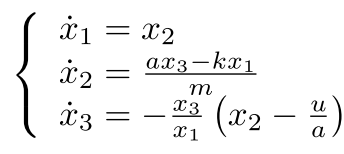

We assume that x1 > 0 the cylinder output distance and x2 its speed of movement. x3 denotes the hydraulic pressure and u the electrical voltage for controlling the output of the cylinder. a, k and m are known constant coefficients.

## Fully controllable dynamics

1. We assume that only position x1 is measured (y = h(x) = x1) 

    (a) Compute the relative degree of the output y(t) with respect to u ? Conclusion.

since x1 is the denominator of the system at 3rd state, it can't be zero. Taking all the x_dot = 0, we can get the equilibrium point: @ [x,u] = [x1 0 k*x1/a, 0] 

    
$$y = x1 \\
dy = dx1 = x2 \\
d2y = dx2 = \frac{a*x3 - k*x1}{m} \\

d3y = d(d2y) = \frac{-a*\frac{x3}{x1}*(x2-\frac{u}{a}) - k*x2}{m} \\
d3y = {\frac{-a*x3*x2}{m*x1} -\frac{k*x2}{m} + \frac{x3}{m*x1}u \\
 where \ dx3 = -\frac{x3}{x1}*(x2-\frac{u}{a}) \\$$


**Conclusion:** I got the control input at the 3rd derivatives of the output, so the relative degree of the system with output y = x1 is **3. The relative degree and the number of states are equal, that means the system is fully controllable (n = r).**

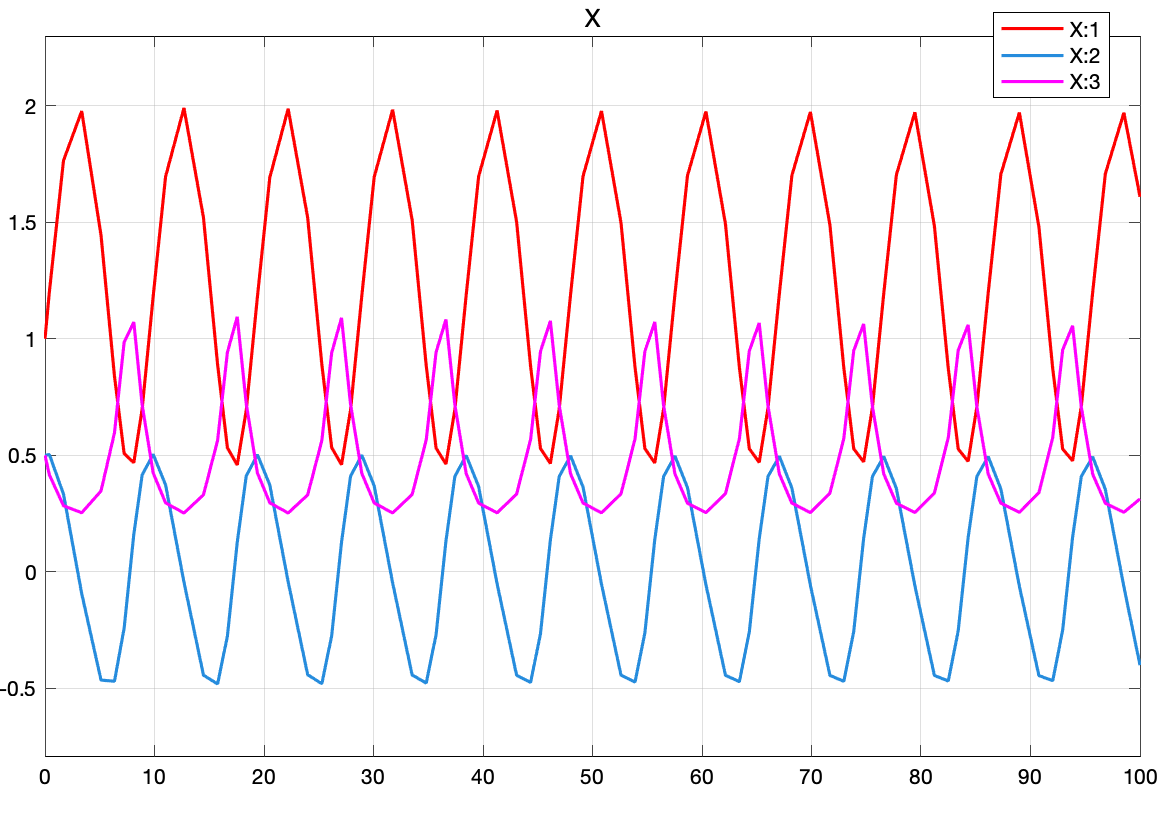

Fig 1: Open loop simulation result

Based on the result, the system is unstable at zero reference input. This is due to nonlinearities caused by state dependency. So, to control this plant, I will use exact linearization.

    (b) We want to make a transformation of the system in the form

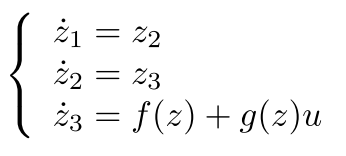

Find the coordinate transformation $z = \psi (x)$ and calculate its inverse $x = \psi ^-1(z).$

$z = \psi (z) =>$ $z1 = x1 \\
z2 = x2 \\
z3 = \frac{a*x3 - k*x1}{m}
$    ===> $x = \psi^{-1} (z)$ =>  $x_1 = z_1 \\
x_2 = z_2 \\
x_3 = \frac{m*z_3 + k*z_1}{a}
$

(c) Propose a control law $u = \gamma(z)$ allowing linearization by input-output loop.


$$\dot{z_1} = z_2 \\
\dot{z_2} = z_3 \\
\dot{z_3} = \frac{-(m*z_3+k*z_1)*z_2}{m*z_1} -\frac{k*z_2}{m} + \frac{m*z_3+k*z_1}{a*m*z_1}u \\
$$


Now, lets use z3_dot = v and our control law will be:


$$ 
f(z) = \frac{-(m*z_3+k*z_1)*z_2}{m*z_1} -\frac{k*z_2}{m} \\
g(z) = \frac{z_3}{a*z_1}+\frac{k}{a*m} \\
u = \frac{1}{g(z)}(-f(z) + v)$$


$\dot{z1} = z2 \\
\dot{z2} = z3 \\
\dot{z3} = v \\
$   ==> $\dot{z} = A*z + B*v \\
$

 where A = $\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
0 & 0 & 0
\end{array}\right\rbrack$ and B = $\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack$

Now, we can control the system using pole placement method;

v = -K*z


$$\dot{z} = A*z + B*v \\
\dot{z} = A*z + B*(-Kz) \ where \ v = -Kz \\
\dot{z} = A*z - BK*z \\
\dot{z} = (A - BK)z \\

$$


Here, K can be calculated from $det(sI - (A-BK)) = 0 \ where \ s = desired \ poles$ OR easiest way using ackerman's matlab function for pole placement.

clc;
A = [0 1 0; 0 0 1; 0 0 0];
B = [0; 0; 1];
C = [1, 0, 0];
D = 0;
p = [-1; -2; -3];
K = acker(A, B, p)

K =      6    11     6


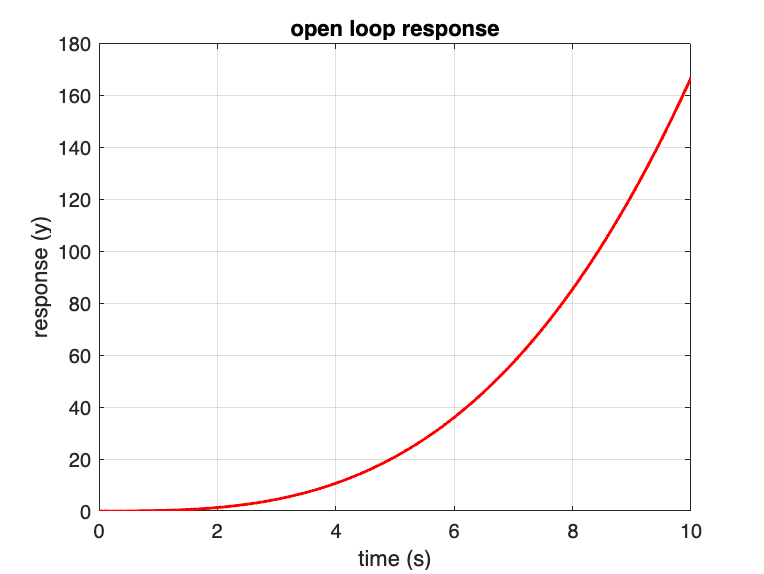


t = 0:0.01:10;    % time vector
r = ones(size(t)); % step input reference

z_ss_o = ss(A,B, C, D); % open loop state space response
[yo, t, xo] = lsim(z_ss_o, r, t);
% Plot the closed-loop output
figure;
plot(t, yo, LineWidth=1.5, Color='red');
xlabel('time (s)');
ylabel('response (y)');
title('open loop response')
grid on;

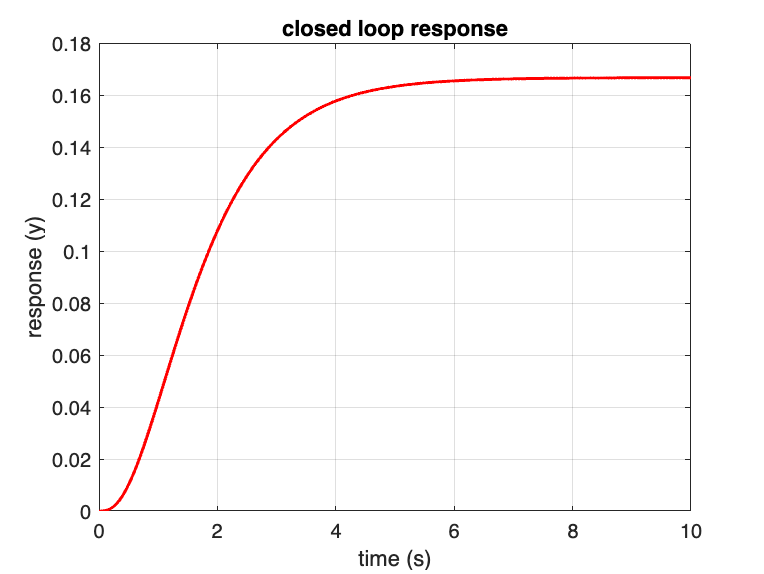


z_ss_c = ss((A-B*K), B, C, D); % open loop state space response
[yc, t, xc] = lsim(z_ss_c, r, t);
% Plot the closed-loop output
figure;
plot(t, yc, LineWidth=1.5, Color='red');
xlabel('time (s)');
ylabel('response (y)');
title('closed loop response');
grid on;

(e) Simulate the system on Matlab/Simulink with the computed controller.

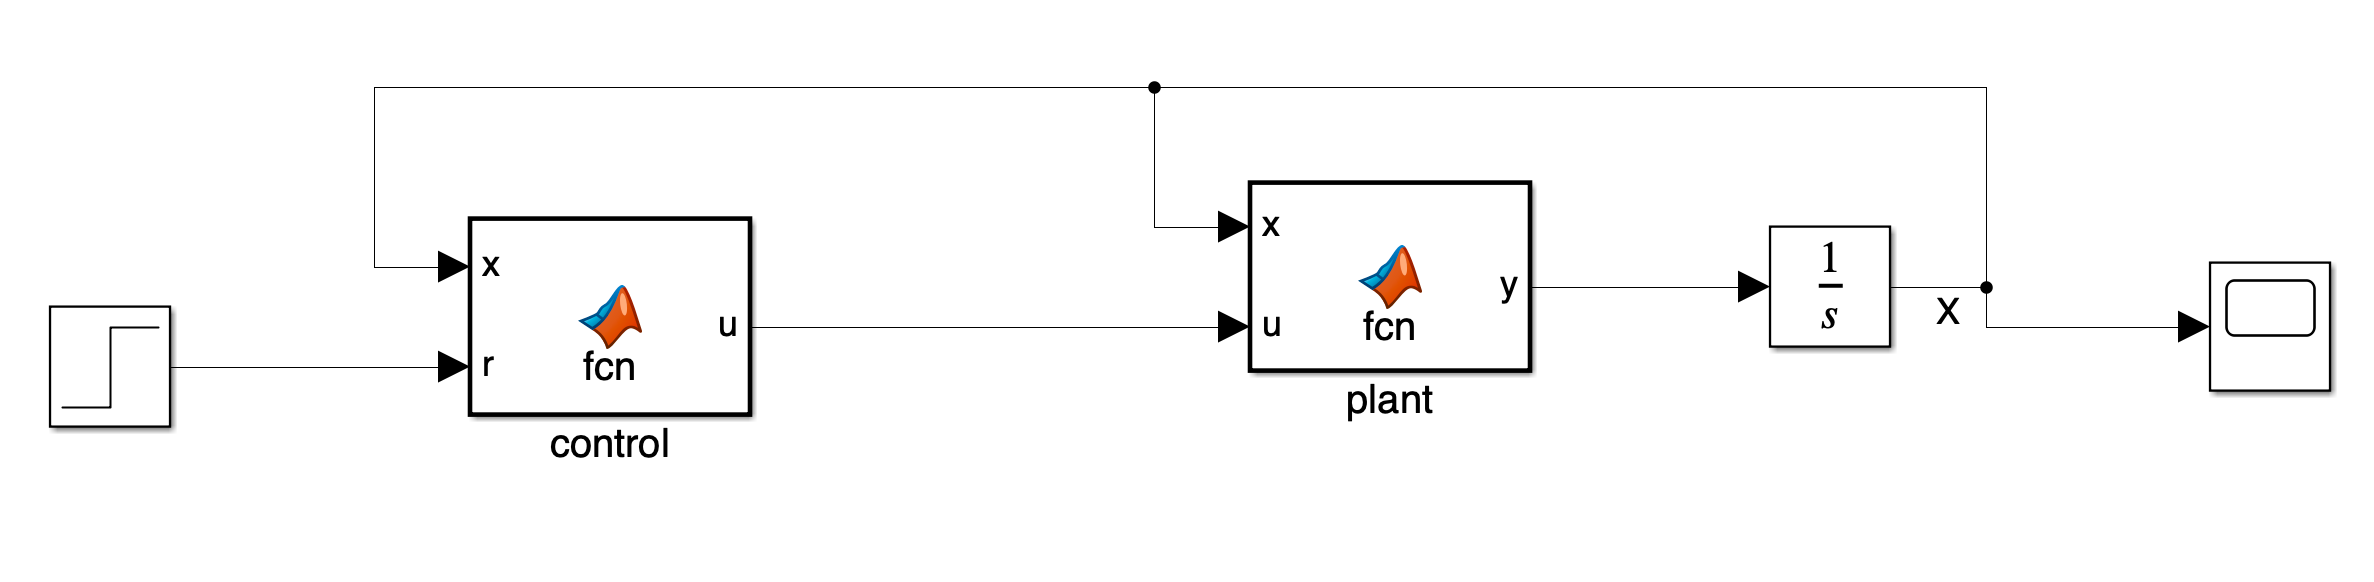

Fig 2: Simulink model of the closed loop plant dynamics

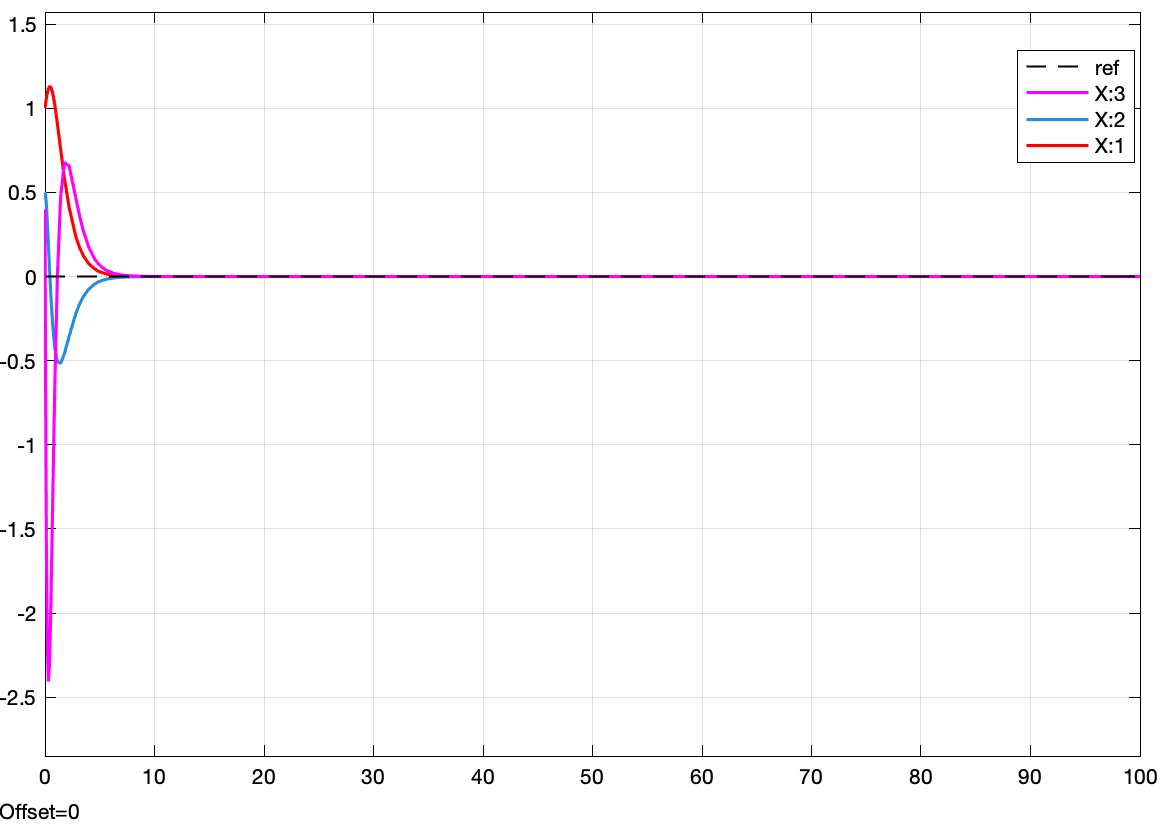

Fig 3: simulation result at zero reference input

Based on the result, it can be concluded that the controller has effectively stabilized the nonlinear plant. The problem of this controller is its settling time which arises from inappropriate pole selection. The poles (-1, -2, -3) are near to the origin and this will obliged the controller for slow tracking and may be also lead to large errors for reference tracking. So, to decrease the transient time, it is recommended to use poles far from the origin. 

## Partially controllable dynamics

2. Now let’s assume that the position is no longer measured but only the velocity (y = x2).

(a) Propose a linearizing control law by input-output looping. 


$$
y = x_2 \\
\dot{y}  = \dot{x_2} = \frac{a*x_3 - k*x_1}{m} \\
\ddot{y} = \frac{-a*\frac{x_3}{x_1}*(x_2-\frac{u}{a}) - k*x_2}{m} \\
\ddot{y}  = {\frac{-a*x_3*x_2}{m*x_1} -\frac{k*x_2}{m} + \frac{x_3}{m*x_1}u \\
 where \  \dot{x_3}  = -\frac{x_3}{x1}*(x_2-\frac{u}{a}) \\$$
 

I got the control input at the 2nd derivatives of the output, so the relative degree of the system with output y = x2 is 2**. The relative degree and the number of states are not equal, that means the system has internal dynamics(r < n). Here, r = 2 and n = 3, which indicates that there is one internal dynamics. **

To analyze stability:

- Force y" = 0 and derive the dynamics for **x3**.

- Assess stability and boundedness of the derived equations.

Lets define the transformation T(x), it must be nonsingular to prevent il-conditioning:

Conditions for stability of the whole dynamics:


$$T\left(x\right)=\left\lbrack \begin{array}{c}
\phi \left(x\right)\\
\psi \left(x\right)
\end{array}\right\rbrack$$


- $\psi \left(0\right)$ = 0

- 
$$\frac{\partial \psi}{\partial x} *g(x) = 0 \ g(x) = [0;  0; \ where \ \frac{x(3)}{a*x(1)}] \ and \ \frac{\partial \psi}{\partial x}  = [\frac{\partial \psi}{\partial x_1} \ \frac{\partial \psi}{\partial x_2} \ \frac{\partial \psi}{\partial x_3}] $$


- T(x) must be invertible

**Lets see each conditions:**

condition 2: To make the condition true, $\frac{\partial \psi}{\partial x_3}$ must be zero; that means  $\psi \left(x\right)$ is dependent on x(1) or x(2) but not on x(3). If we take $\psi \left(x\right)$ = x(2), T(x) will not be invertible due to rank of T(x) will reduced. So, x(1) has a possibility.

condition 1: after checking condition 2, x(1) is the remaining to check for this condition. But x(1) is greater than zero at zero. That means x(1) doesn't satisfy the condition.

Now lets see check the combined version of x(1) and x(2)

==> x1x2 , x1/x2, x1+x2, and x1-x2 ---> all those combination choices will make the system unstable, too.

**My only option is to take a false assumption, which is x1 has a chance to have zero value even though it is not true due to the first condition violation. This assumption will help me to continue the next calculations, but it will end up with unstable result. This is due to the plant dynamics has x1 as a denominator.**

==> $\psi \left(x\right)$ = x(1), this will make T(x) invertible. Now, we can rewrite the T(x) matrix.

$T\left(x\right)=\;\left\lbrack \begin{array}{c}
\textrm{z1}\\
\textrm{z2}\\
\eta 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\textrm{x2}\\
\frac{\left({a*x}_3 -{k*x}_1 \right)}{m}\\
x_1 
\end{array}\right\rbrack$ ==> ${T\left(z\right)}^{-1}$ = $\left\lbrack \begin{array}{c}
x_2 \\
x_3 \\
x_1 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
z_1 \\
\frac{\left({m*z}_2 +k*\eta \right)}{a}\\
\eta 
\end{array}\right\rbrack$

$\dot{z_1}  = \dot{x_2} = \frac{a*x_3 - k*x_1}{m} \\
\dot{z_2}  = {\frac{-a*x_3*x_2}{m*x_1} -\frac{k*x_2}{m} + \frac{x_3}{m*x_1}u \\
\dot{\eta} = \dot{x_1} = x_2 \\$    ==>    $\dot{z_1}  = \frac{a*x_3 - k*\eta}{m} \\
\dot{z_2}  = {\frac{m*z_2 + k*\eta}{m*\eta} z_1 - \frac{k*z_1}{m} + \frac{m*z_2 + k*\eta}{a*m*\eta}u \\
\dot{\eta} = \dot{x_1} = z_1$  

since x_1 > 0, $\eta$' depends on x1 and x3

$u=\frac{a*m*\eta }{m*z_2 +k*\eta }\left(v+\frac{m*z_2 +k*\eta }{m*\eta }z_1 +\frac{k}{m}z_1 \right)$ -----> the control law

$\dot{z_1} = z_2 \\
\dot{z_2} = v
$ ==> $\dot{z} = A*z + B*v$,

where A = $\left\lbrack \begin{array}{cc}
0 & 1\\
0 & 0
\end{array}\right\rbrack$and B = $\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack$

Now, we can calculate the closed loop gains using pole placement.

(b) Give the characterization of dynamic zeros (internal dynamics).

**Lyapunov based characterization:**

A common choice for the Lyapunov candidate function is a quadratic function of the system states:


$$V(\eta, x_2, x_3) = \frac{1}{2} \eta^2 + \frac{1}{2} x_2^2 + \frac{1}{2} x_3^2
$$



$$\dot{V} = \frac{\partial V}{\partial \eta} \dot{\eta} + \frac{\partial V}{\partial x_2} \dot{x}_2 + \frac{\partial V}{\partial x_3} \dot{x}_3
$$



$$\dot{V} = \eta x_2 + \frac{a x_2 x_3}{m} - \frac{k x_2 \eta}{m} - \frac{x_3^2 x_2}{\eta} + \frac{x_3^2 u}{a \eta}
$$


Open-Loop Stability (u=0):


$$\dot{V} = \eta x_2 + \frac{a x_2 x_3}{m} - \frac{k x_2 \eta}{m} - \frac{x_3^2 x_2}{\eta}
$$


The sign of $\dot{V}$ depends on the interplay between the terms:

- $\eta *\textrm{x2}$: Can be positive or negative, depending on the sign of x2, since $\eta$ > 0.

- $a*\textrm{x2}*\textrm{x3}/m$: Depends on x2*x3.

- $-k*\textrm{x2}*\eta /m$: Introduces damping if k>0.

- $-\textrm{x3}ˆ2*\textrm{x2}/\eta$: Can destabilize if η→0.

Since $\dot{V}$ is not definitively negative, the system is **not Lyapunov stable** in open loop.

**Conclusion**

- **Open-Loop System:** The Lyapunov derivative $\dot{V}$ is not definitively negative, means the system is **not Lyapunov stable** in open loop. 

- Even with feedback, the singularity at η=x1=0 makes the system inherently unstable. This reflects the fact that the internal dynamics (zero dynamics) of the system are unstable.

(c) What can we say about the dynamics of zeros ? 

Zero dynamics is determined by the behavior of x3, which is the 3rd state under the constraints. But this result is due to the false assumption. In reality the system has unstable zero dynamics.

**Unstable Zero Dynamics:**

- If the zero dynamics are unstable (internal states grow unbounded), the system is **non-minimum phase**. In this case, input-output linearization is not practical because the plant’s internal dynamics will destabilize the system.

**Here, for the given model, I tried all possibilities that satisfy the conditions for stability, however I ended up with no success. So, I concluded that the system has minimum phase and unstable zero dynamics. Exact linearization is not a practical solution for this dynamics.**

(d) Simulate the system on Matlab/Simulink with the computed controller.

Based on the false assumption, I developed the following controller. 

A2 = [0 1; 0 0];
B2 = [0; 1];
C2 = [1 0];
D = 0;
p = [-2; -3];
K2 = acker(A2, B2, p)

K2 =      6     5


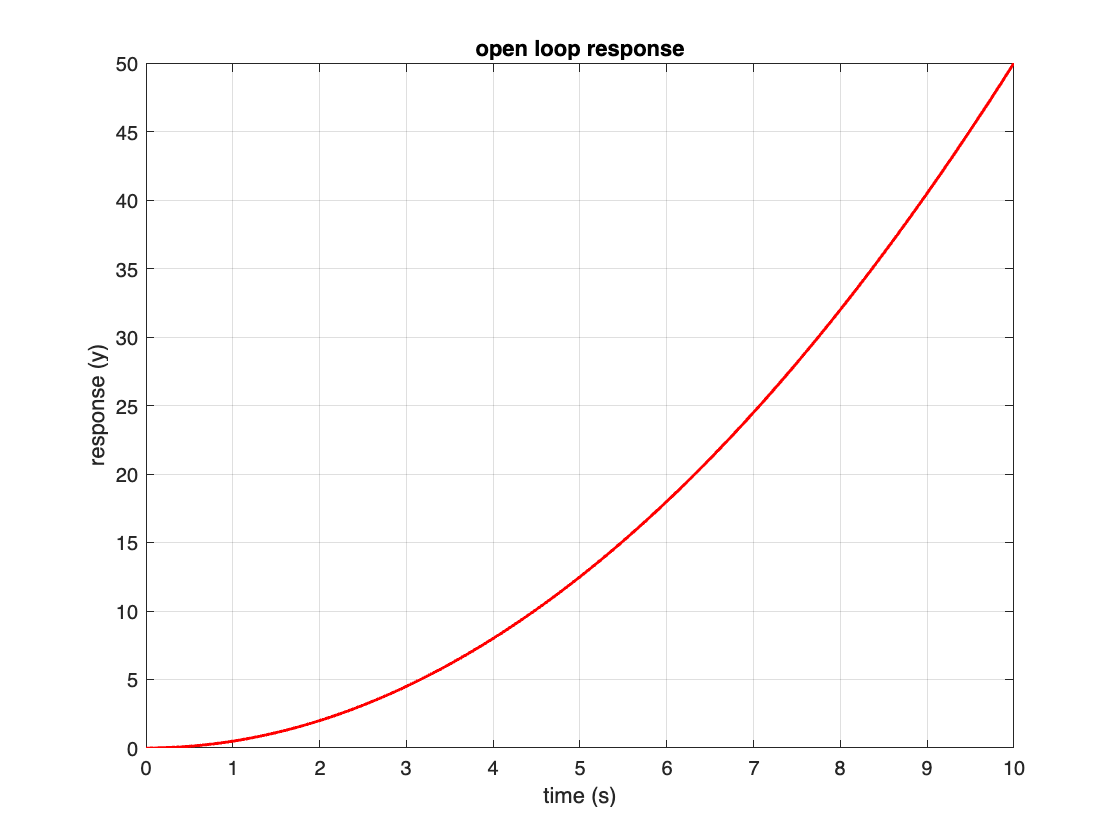



t = 0:0.01:10;    % time vector
r = ones(size(t)); % step input reference

z_ss_o2 = ss(A2, B2, C2, D); % open loop state space response
[y2o, t, x2o] = lsim(z_ss_o2, r, t);
% Plot the closed-loop output
figure;
plot(t, y2o, LineWidth=1.5, Color='red');
xlabel('time (s)');
ylabel('response (y)');
title('open loop response')
grid on;

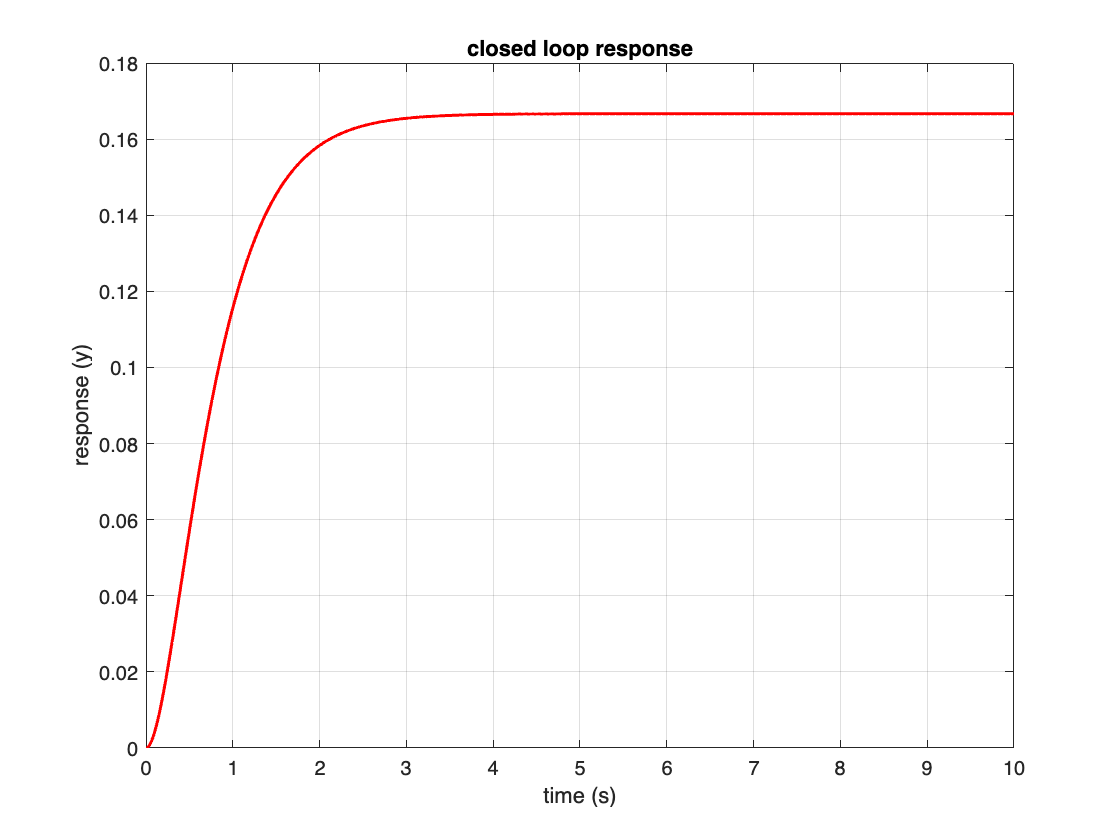


z_ss_c2 = ss(A2-B2*K2, B2, C2, D); % closed loop state space response
[y2c, t, x2c] = lsim(z_ss_c2, r, t);
% Plot the closed-loop output
figure;
plot(t, y2c, LineWidth=1.5, Color='red');
xlabel('time (s)');
ylabel('response (y)');
title('closed loop response');
grid on;

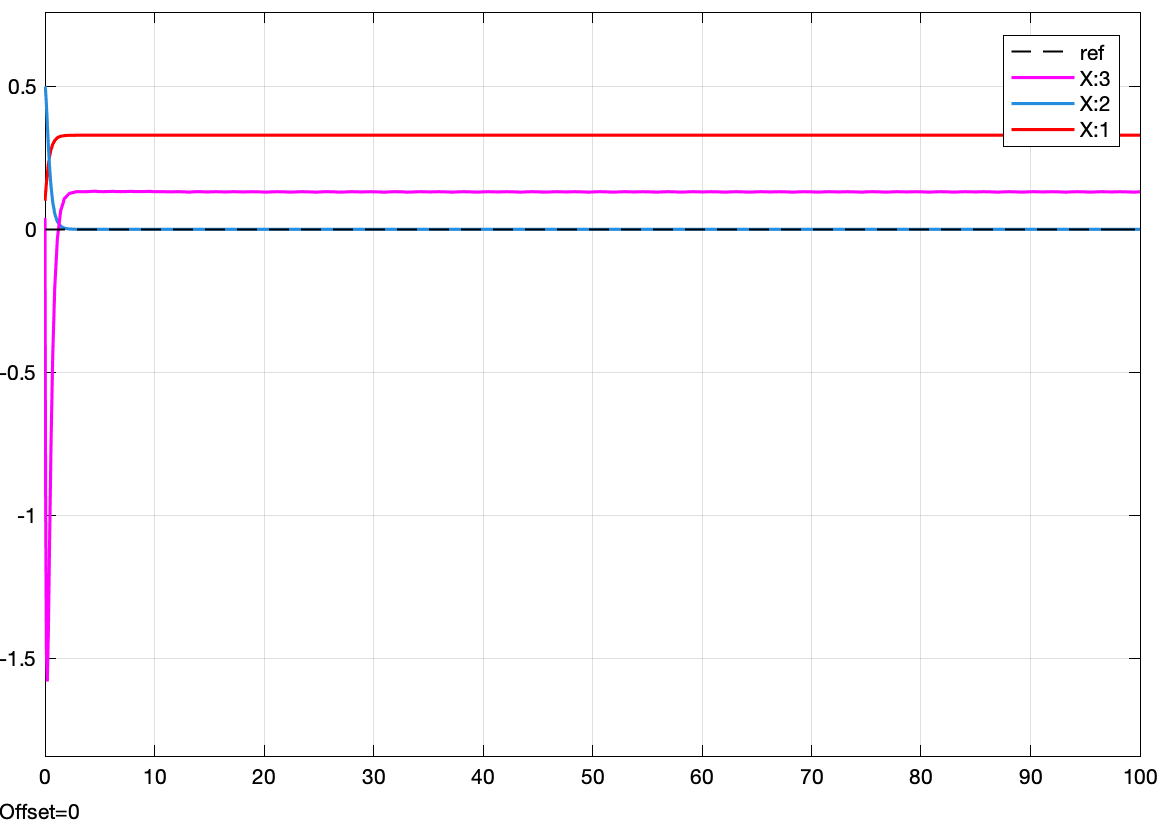

Fig 4: Simulation result of the partially controllable plant

Based on the result for the false assumption, the plant is stabilized at zero reference input. Compared to the fully controllable model, it has higher settling time higher transient overshot for the first state and less overshot for the 3rd state. The problem for this controller is a small change in the reference leads x1 and x2 to higher change since state x1 is unmeasured. The states x1 and x3 are also stabilized at constant non-zero values at zero input, this will result unstable output when the input is changed. By using augmentation, I can damp the non-zero state result, such as adding -k*x3 into the control dynamics. However, this will damp state x2, and it will be hard to track reference inputs for x2.

## Trajectory tracking

3. In both the two cases, modify the controller in order to track a reference trajectory for the position x1(t) given by :

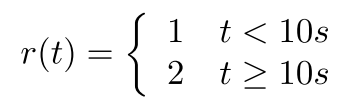

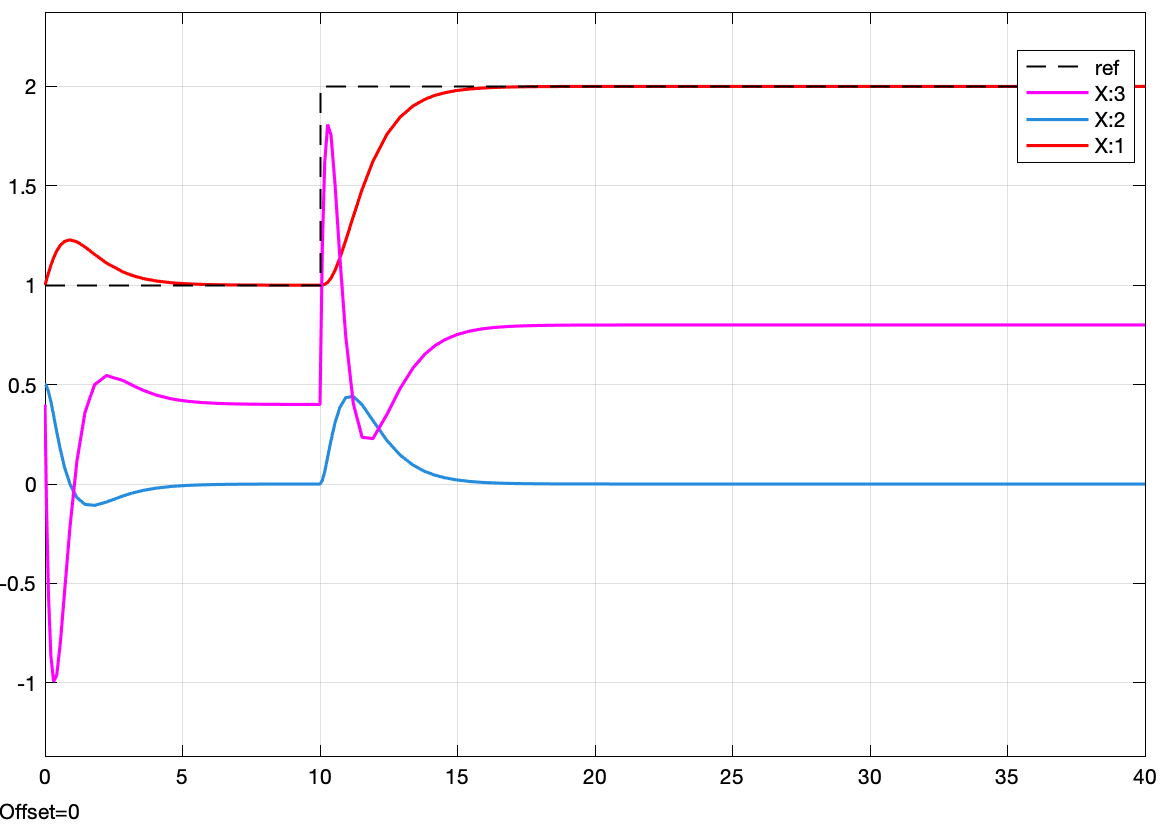

Fig 5: Reference tracking for the fully controlled plant model

As we can see from the result, the controller perfectly managed the plant to track the reference input. However, state x3 is dependent on state x1. This state dependency led the 3rd state to non-zero stable result. The result indicates that the plant is dynamically stable for the given conditions, showing no signs of divergence or instability. The settling time is less than 5 seconds, its overshot is minimum and steady state error is around zero. This is the behavior of a good controller. Generally, the controller appears effective in stabilizing the system and achieving the desired behavior.

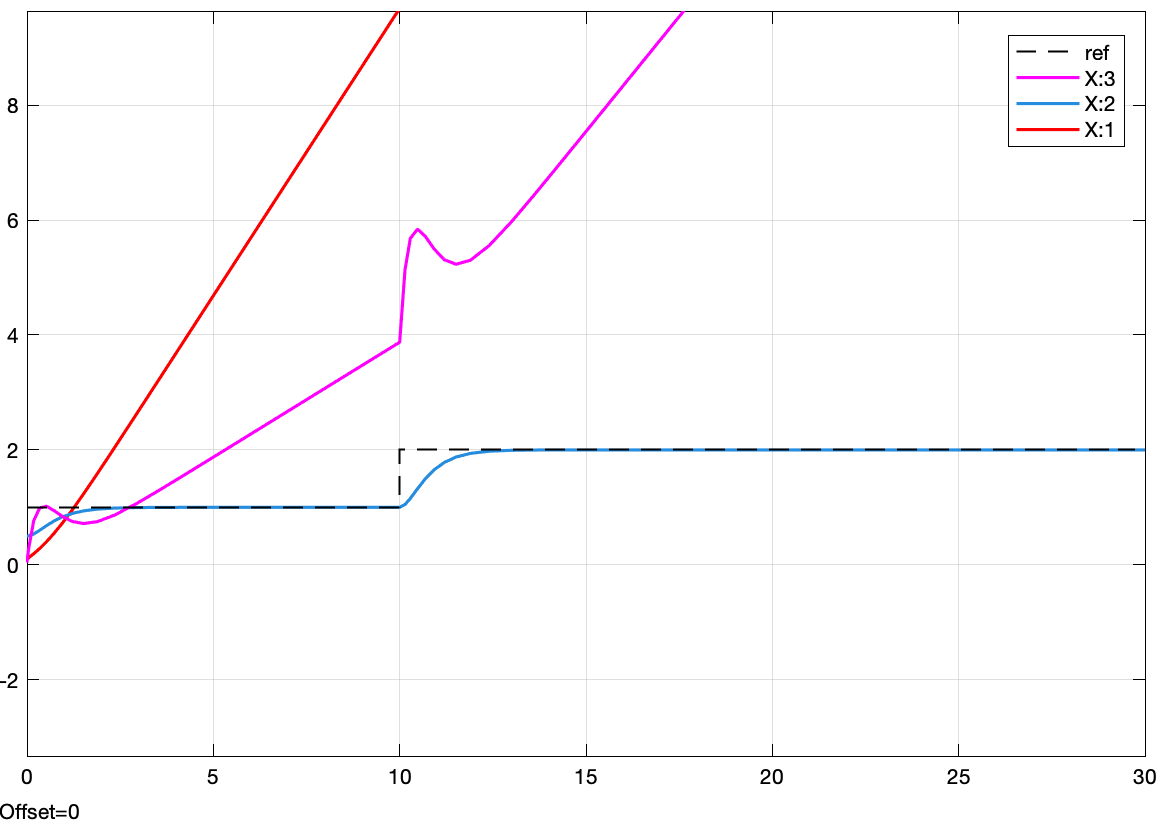

Fig 6: Reference tracking for the partially controlled plant model

Based on the result, I concluded that the plant is not completely stable due to state x1 and x3 diverged when I applied a non-zero reference input. However, state x2 is stable and perfectly tracked the reference input with in 3 seconds. Based on this result, I can say that the unstable dynamics has no effect on the state x2. The unstable internal dynamics only influence the states x1 and x3, which is divergent as time goes infinity.

## Reference

- my lecture notes

- Khalil, H. K. (1996). *Nonlinear systems* (2nd ed.). Prentice Hall.

## Appendix

Complete Simulink model 

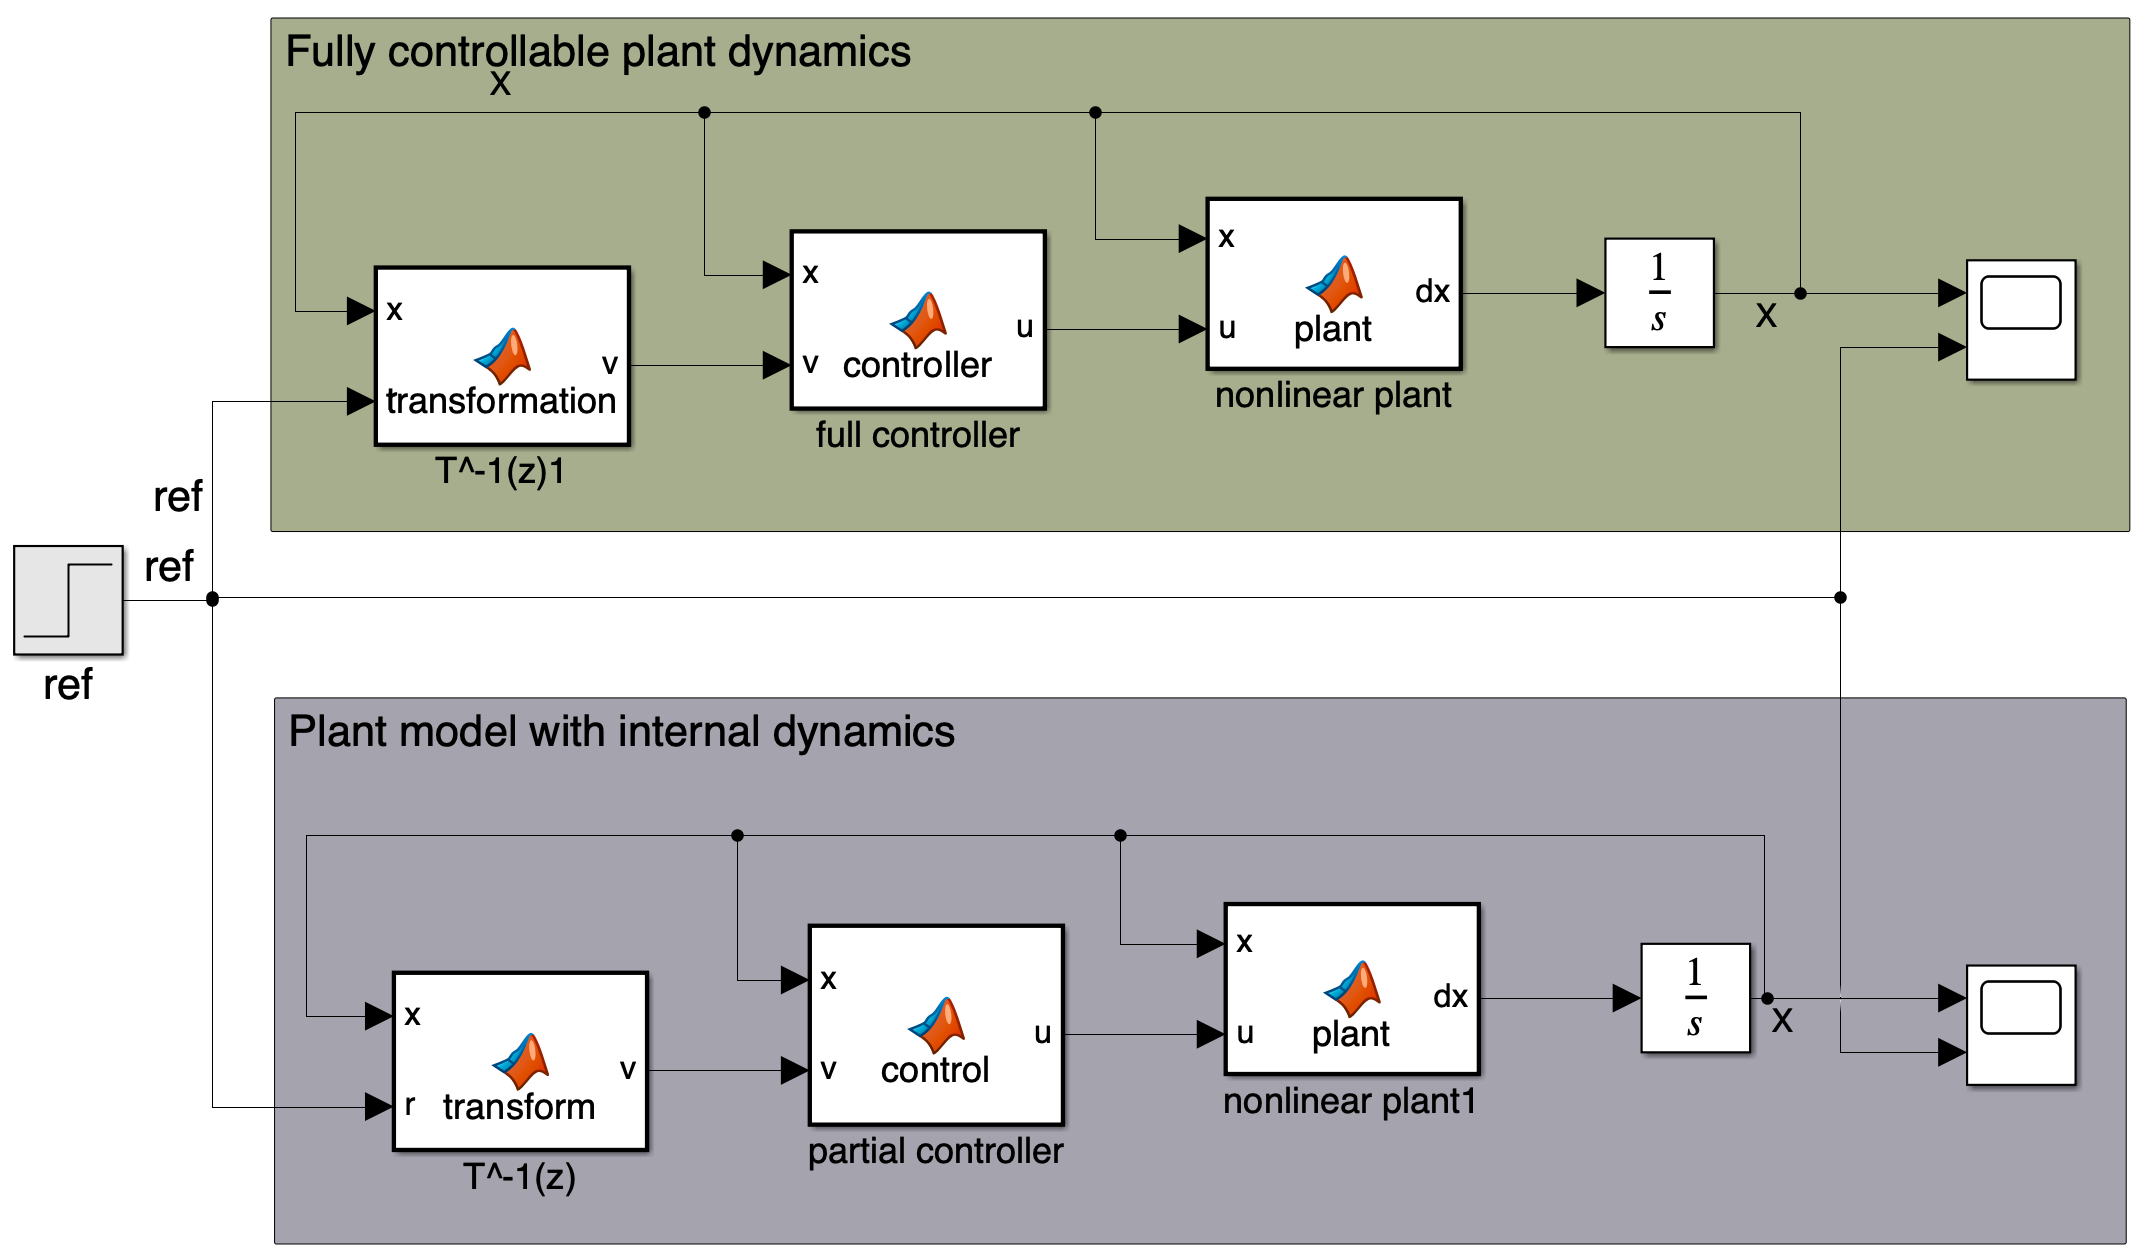

Nonlinear plant dynamics function

function dx = plant(x,u)
dx = zeros(3,1);
a = 1; k = 0.4; m = 2;
dx(1) = x(2);
dx(2) = (a*x(3)-k*x(1))/m;
dx(3) = -(x(3)/x(1))*(x(2)-u/a);
end

full controller function

% u - control law
function u = controller(x,v)
a = 1; k = 0.4; m = 2;
u = (v + a*x(3)*x(2)/(m*x(1)) + k*x(2)/m)*(m*x(1))/(x(3));
end

% feedback in z 
function v = transformation(x, r, K)
a = 1; m = 2; k = 0.4;
z1 = x(1);
z2 = x(2);
z3 = (a*x(3)-k*x(1))/m;
v = K(1)*(r-z1)-K(2)*z2 - K(3)*z3;
end

Partial controller function

% u - control law
function u = control(x,v)
a = 1; k = 0.4; m = 2;
u = (m*x(1)/x(3))*(v + (a*x(3)*x(2)/(m*x(1)))+(k*x(2)/m));
end

% feedback in z 
function v = transform(x, r, K2)
a = 1; m = 2; k = 0.4;
z1 = x(2);
z2 = (a*x(3)-k*x(1))/m;
v = K2(1)*(r-z1)-K2(2)*z2;
end
